# Land Cover Classification

You will train a network that classifies 28-by-28-by-4 images into six categories. These categories are shown in the image below:

- barren land

- building

- grassland

- road

- trees

- water

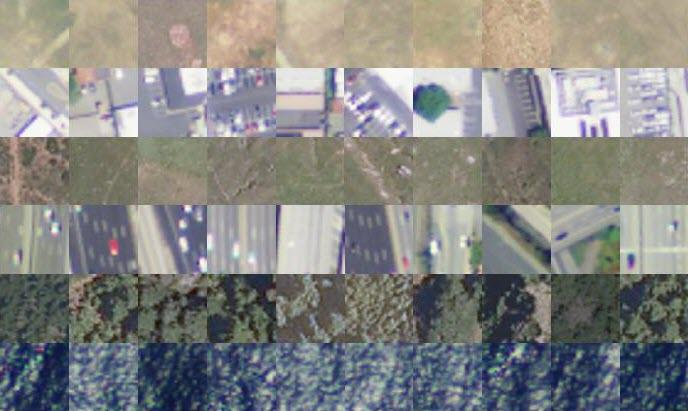

*satData.mat* includes XTrain, XTest, XVal **data**s and YTrain, YTest, YVal class **label**s

load satData.mat

layers = [
    imageInputLayer([28 28 4])
    convolution2dLayer(3,20)
    reluLayer()
    maxPooling2dLayer(3)
    fullyConnectedLayer(6)
    softmaxLayer()
    classificationLayer()
    ]

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×4 images with 'zerocenter' normalization
     2   ''   Convolution             20 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             3×3 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected         6 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

valData = {XVal, YVal}

valData = 1×2 cell array
    {28×28×4×600 uint8}    {600×1 categorical}


options = trainingOptions("sgdm","MaxEpochs",4,"InitialLearnRate",0.0001, "Plots","training-progress", "ValidationData",valData, "ValidationFrequency",10);

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        3.91% |       34.33% |      49.9042 |      70.4846 |      1.0000e-04 |
|       1 |          10 |       00:00:01 |       81.25% |       75.50% |      13.9190 |      35.0812 |      1.0000e-04 |
|       1 |          20 |       00:00:01 |       78.12% |       80.17% |      27.0682 |      26.9278 |      1.0000e-04 |
|       2 |          30 |       00:00:01 |       85.94% |       87.00% |      13.1955 |   

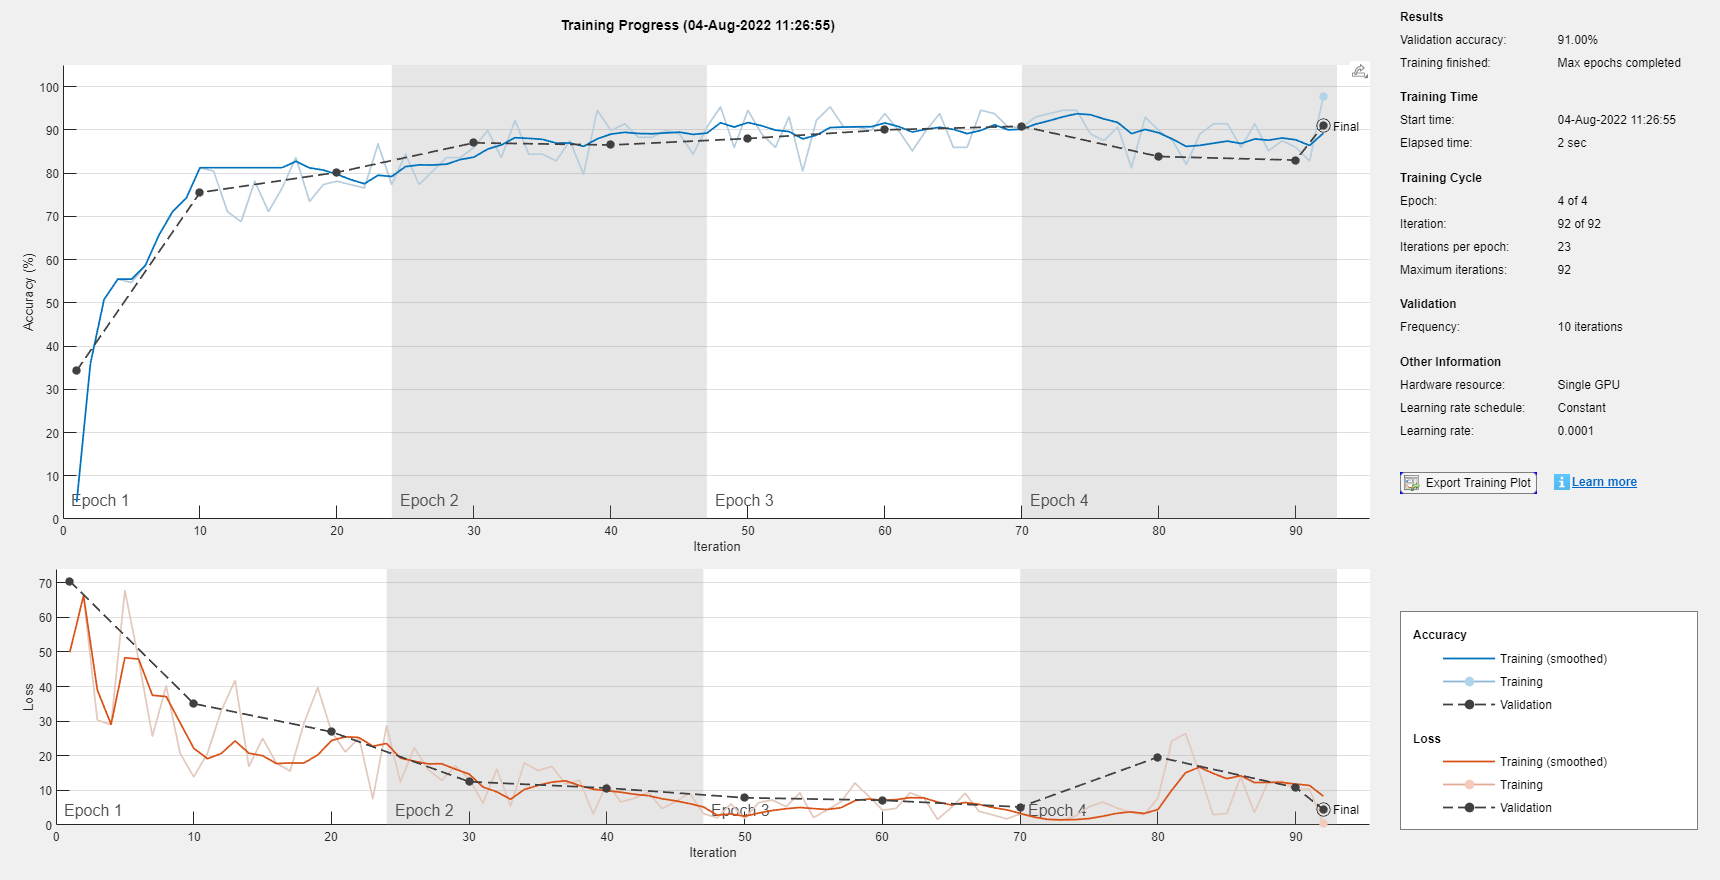

landnet =   SeriesNetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


landnet = trainNetwork(XTrain,YTrain,layers,options)

testpreds = classify(landnet,XTest);
nnz(testpreds == YTest)/numel(testpreds)

ans = 0.9050

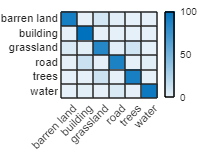


[conf,names] = confusionmat(YTest,testpreds);
heatmap(names,names,conf);